# Respuesta en Frecuencia

##  Como paso previo para analizar los problemas acústicos, debemos contar con la siguiente información:

### 1. Respuesta en frecuencia de la sala (informe anterior).

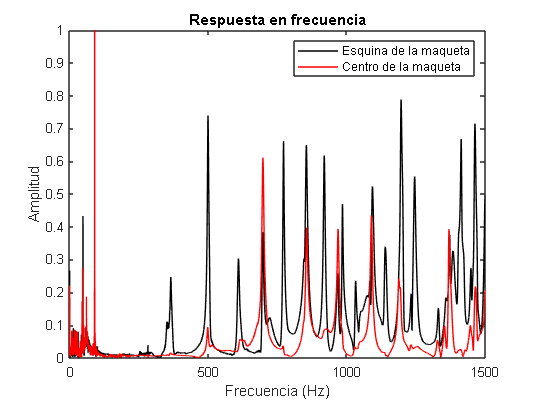

[esquina1, fs_esquina] =audioread('esquina1.wav');
[centro1, fs_centro] = audioread('centro1.wav');

% Calcular numero de puntos
numero_pts_centro = 2^ceil(log2(length(centro1)));   
numero_pts_esquina = 2^ceil(log2(length(esquina1)));
% Se hace para simplificar los cálculos de la FFT.

% Calculamos la Transformada de Fourier
fft_esquina=fft(esquina1,numero_pts_esquina);
fft_centro =fft(centro1,numero_pts_centro);

x_c = fs_centro*(0:(numero_pts_centro-1))/numero_pts_centro;
x_e = fs_esquina*(0:(numero_pts_esquina-1))/numero_pts_esquina;

% Representamos la respuesta en frecuencia
figure(1)
plot(x_e,abs(fft_esquina/max(fft_esquina)),'k');
hold on
plot(x_c,abs(fft_centro/max(fft_centro)),'r');
xlim([0,1500]);
xlabel('Frecuencia (Hz)');
ylabel('Amplitud');
title('Respuesta en frecuencia');
legend('Esquina de la maqueta','Centro de la maqueta');
hold off

###  2. Análisis espectral de la señal original, antes de ser reproducida en la sala.

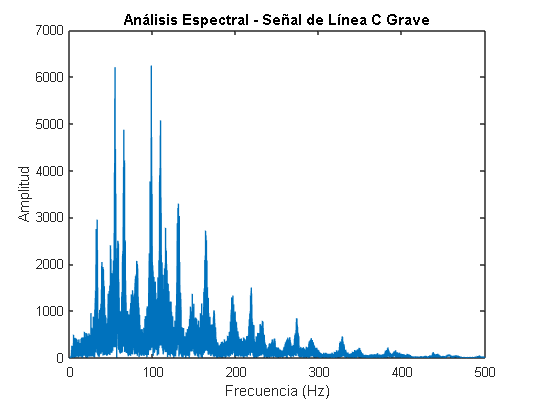

% Leer la señal
[linea_Cgrave, fs_linea_Cgrave] = audioread('linea_Cgrave.wav');

% Calcular numero de puntos
numero_pts_bajo = 2^ceil(log2(length(linea_Cgrave))); 

% Calculamos la Transformada de Fourier
fft_bajo=fft(linea_Cgrave,numero_pts_bajo);

x_bajo = fs_linea_Cgrave*(0:(numero_pts_bajo-1))/numero_pts_bajo;

% Graficar el análisis de frecuencia
figure(2)
plot(x_bajo, abs(fft_bajo));
xlabel('Frecuencia (Hz)');
ylabel('Amplitud');
title('Análisis Espectral - Señal de Línea C Grave');
xlim([0,500])

###  3. Análisis espectral de señales grabadas en la maqueta.

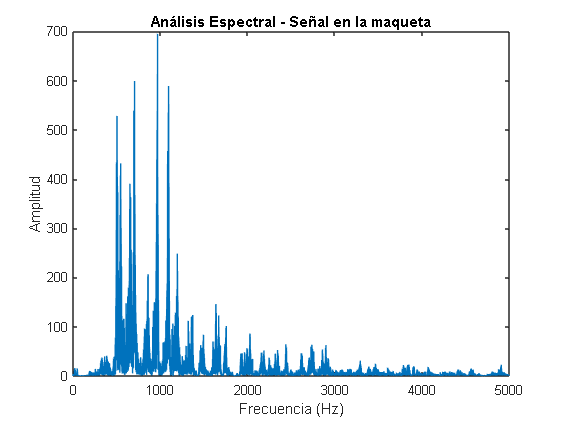

% hay que representar como es la fft de la señal de bajo en el mundo real,
% es decir, las frecuencias son 10 veces más que antes y la atenuación por
% la distancia.
[bajo_rapido fs_rapida]=audioread("svacia.wav");
% bajo_interpolado=interp(bajo_rapido,10);
% Calcular numero de puntos
numero_pts_bajo_maqueta = 2^ceil(log2(length(bajo_rapido))); 
% Calculamos la Transformada de Fourier
fft_bajo_interp=fft(bajo_rapido,numero_pts_bajo_maqueta);

x_bajo_interp = fs_rapida*(0:(numero_pts_bajo_maqueta-1))/numero_pts_bajo_maqueta;

% Graficar el análisis de frecuencia
figure(3)
plot(x_bajo_interp,abs(fft_bajo_interp));
xlabel('Frecuencia (Hz)');
ylabel('Amplitud');
title('Análisis Espectral - Señal en la maqueta');
xlim([0,5000])

###  Tarea: Obtenga la frecuencia fundamental de las 10 primeras notas de la señal original (línea de bajo).

% Notas extraídas con Audacity

[nota1, fs_nota1] = audioread("Nota1.wav");
[nota2, fs_nota2] = audioread("Nota2.wav");
[nota3, fs_nota3] = audioread("Nota3.wav");
[nota4, fs_nota4] = audioread("Nota4.wav");
[nota5, fs_nota5] = audioread("Nota5.wav");
[nota6, fs_nota6] = audioread("Nota6.wav");
[nota7, fs_nota7] = audioread("Nota7.wav");
[nota8, fs_nota8] = audioread("Nota8.wav");
[nota9, fs_nota9] = audioread("Nota9.wav");
[nota10, fs_nota10] = audioread("Nota10.wav");

% Calcular la Transformada de Fourier y encontrar la frecuencia fundamental para cada nota
frecuencias_fundamentales = zeros(1, 10);

notas = {nota1, nota2, nota3, nota4, nota5, nota6, nota7, nota8, nota9, nota10};
frecuencias_muestreo = [fs_nota1, fs_nota2, fs_nota3, fs_nota4, fs_nota5, fs_nota6, fs_nota7, fs_nota8, fs_nota9, fs_nota10];

% Obtener las frecuencias fundamentales de las notas
frecuencias_fundamentales = getFundamentalFrequency(notas, frecuencias_muestreo);

% Mostrar las frecuencias fundamentales de las 10 primeras notas
disp('Frecuencias fundamentales de las 10 primeras notas del bajo:');

Frecuencias fundamentales de las 10 primeras notas del bajo:


disp(frecuencias_fundamentales);

  Columns 1 through 8

   32.4265   38.8889   49.0000   54.5117   42.5676   32.7637   33.6898   32.7151

  Columns 9 through 10

   39.8014   48.7832



save('frecuencias_fundamentales.mat', 'frecuencias_fundamentales');
